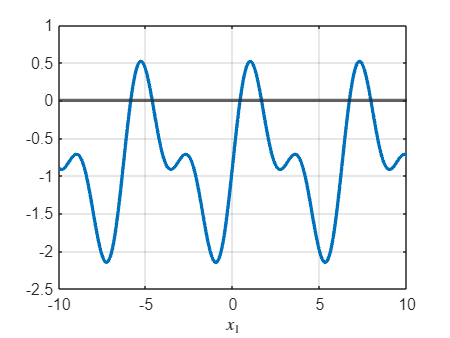

% given parameters
P=0.815; EFD=1.22; eta_1=2; eta_2=2.7;
eta_3=1.7; tau=6.6; M=0.0147;

% solve for x1
t = linspace(-10,10,1000);
f = @(x1) eta_1./eta_2*(eta_3.*cos(x1)+EFD).*sin(x1)-P;
plot(t,f(t),'LineWidth',2); 
hold on; grid on;
yline(0,'LineWidth',2);
hold off;
xlabel('$x_1$','Interpreter','latex')

f1 = fzero(f,0.4)

f1 = 0.4067

f2 = fzero(f,1.6)

f2 = 1.6398


% solve for x3
g = @(x1) eta_3/eta_2*cos(x1)+EFD/eta_2;
g1 = g(f1)

g1 = 1.0301

g2 = g(f2)

g2 = 0.4085